# A how to guide in using the Entropy Coefficient Estimator class. Generate multilevel temperature signals for each SoC and estimate the entropy coefficient

**WMG, University of Warwick, TVT, Karlsruhe Institute of Techology**

W.D. Widanage 05/10/2021 (Still quite)

## Step 1: Generate a multilevel temperature signal

Generate a second reference signal with different settings

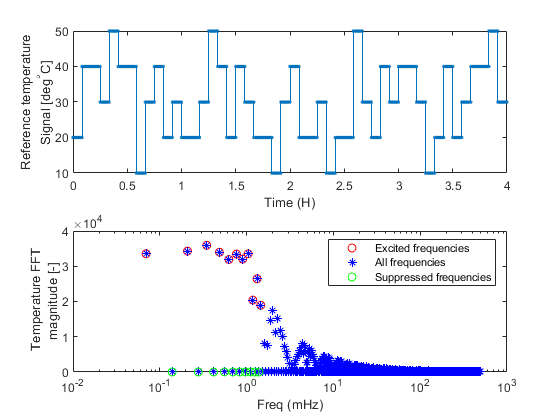

clear
clc
close all

% Generate a reference signal with the default settings and plot the signal
ecObj = EntropyCoeffEstimator(); 
ecObj.PlotRefSig

% Generate a second reference signal with different settings and plot the
% signal
ecObj = EntropyCoeffEstimator("Tmax_degC",50,"Tmin_degC",40,"numLevels",3,"startTemp",46,"fMax_Hz",1.5e-3,"Ts_s",2);

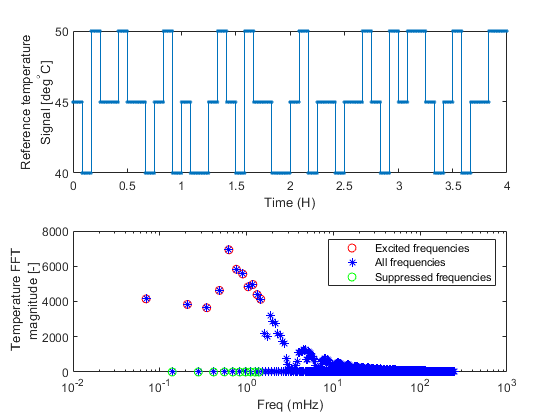

ecObj.PlotRefSig

## Step 2: Import measured OCV and temperature data

ecObj.ImportLegacyRefSig("filePth","MeasurementData\dUdTdata_T0060_SOC50_2_frequencycontrolled\1020\refTempSig_1020_1.mat");
ecObj.ImportOCVData("filePth","MeasurementData\dUdTdata_T0060_SOC50_2_frequencycontrolled\1020\202109252355_Feld1.txt"); 
ecObj.ImportTemperatureData("filePth","MeasurementData\dUdTdata_T0060_SOC50_2_frequencycontrolled\1020\202109252355_Feld2.txt",...
                                 "HdrNames",["Time_s", "BoxDeckel", "MinusPol", "LIBMinusUnten", "LIBMinusOben", "LIBPlusUnten", "LIBPlusOben", "PlusPol", "LIBMitteOben", "LIBMitteUnten", "KuhlblockOben", "Raum", "SollTemp", "TECRefUnten", "TECRefOben"]); 

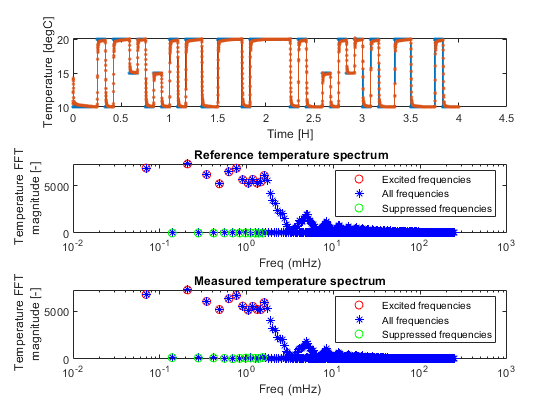

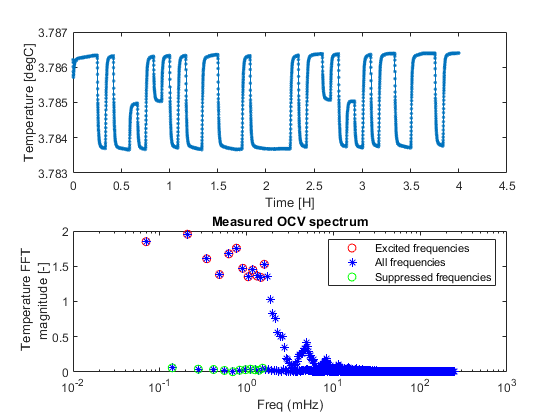

ecObj.PlotProcessedSig

## Step 3: Estimate dudt

ecObj.EstimateEntropyCoeff("modelOrder_denom",2,"modelOrder_num",1);



Iteration terminated:  Parameter update is smaller than specified tolerance, TolDT = 1e-06.


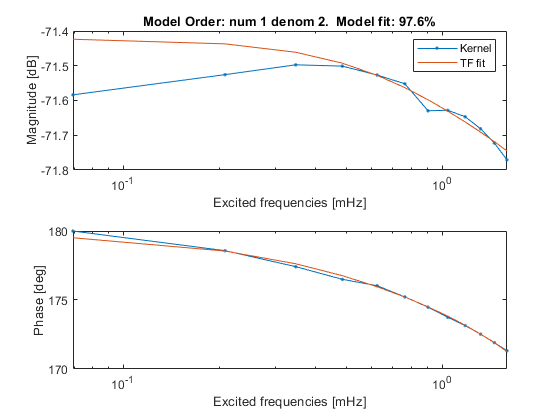

ecObj.PlotKernelFit

ecObj.results.dUdT_mVpK

ans = -0.2685

ecObj.results.dUdT_std

ans = 6.2598e-04